# DeepInterpolation - Tiny Ophys Inference Example

This example imports and uses a pre-trained DeepInterpolation model in MATLAB for inferring tiny ophys sample data.

## Initialize path

deepinterp.setup();

## Import and Assemble Model

The pre-trained network is available on an external file storage, as it is a bit larger (120 MB) than the other example networks. It is automatically downloaded by `deepinterp.` here. This is a file generated by the TensorFlow  package in Python. 

deepinterpnet = deepinterp.getPretrainedModel('TP-Ai93-450');

Importing the saved model...
Translating the model, this may take a few minutes...
Finished translation. Assembling network...
Import finished.


## Import Sample TIFF Volume

ophys = single(tiffreadVolume('ophys_tiny_761605196.tif'));
[ophysNorm, C, S] = normalize(ophys,3,"center","mean","scale","std"); % where C = mean, S = std

## **Perform DeepInterpolation**

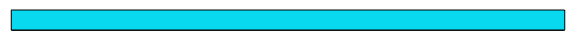

ophysInterpNorm = deepinterpnet.interp(ophysNorm,'progbar',1);

ophysInterp = ((ophysInterpNorm .* S)+C);

## Plot input and output

Show processed frames (from 31 ... 100-30 ).

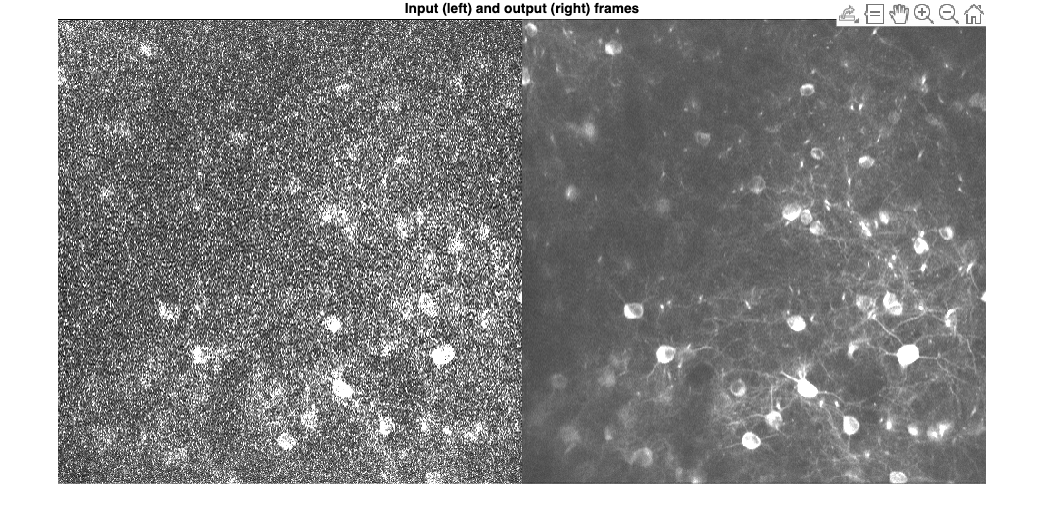

figure;
for idx = 31:size(ophys,3)-30
    imshow([ophys(:,:,idx) ophysInterp(:,:,idx)],...
        [0 prctile(ophys(:),95)]);  % scaling image to 0 .. 95 percentile to show range
    pause(0.1);
end
title("Input (left) and output (right) frames")